%dir_input = 'C:\Users\rsarin\Google Drive\ArmEMG\Data\SEEDS\FeaturesSubj\';
dir_input = 'C:\Users\saman\Google Drive\HAL\Projects\ArmEMG\Data\SEEDS\FeaturesSubj\';
fname_input = '-SEEDSfeatures'; %Tag for file name (follows subject name)
includedspeeds={'both','slow','fast'}; %cell array of all speeds
sp = 1 %speed we want to examine

sp = 1

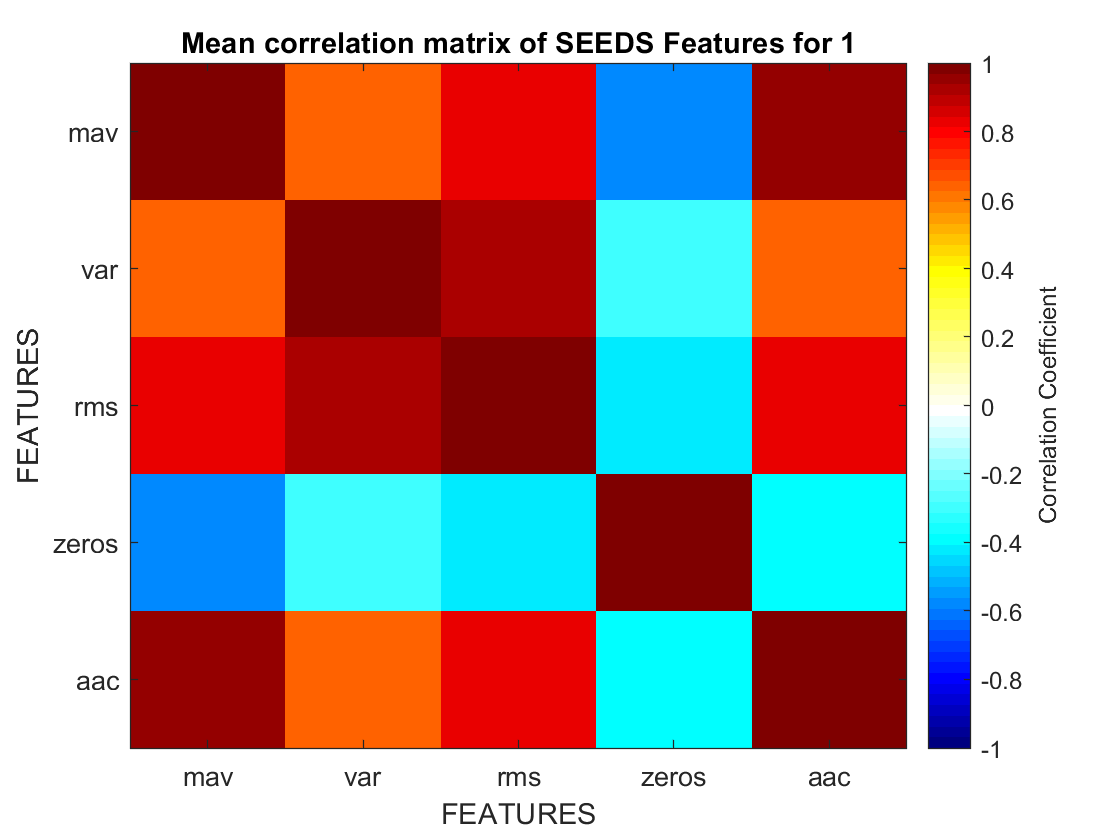

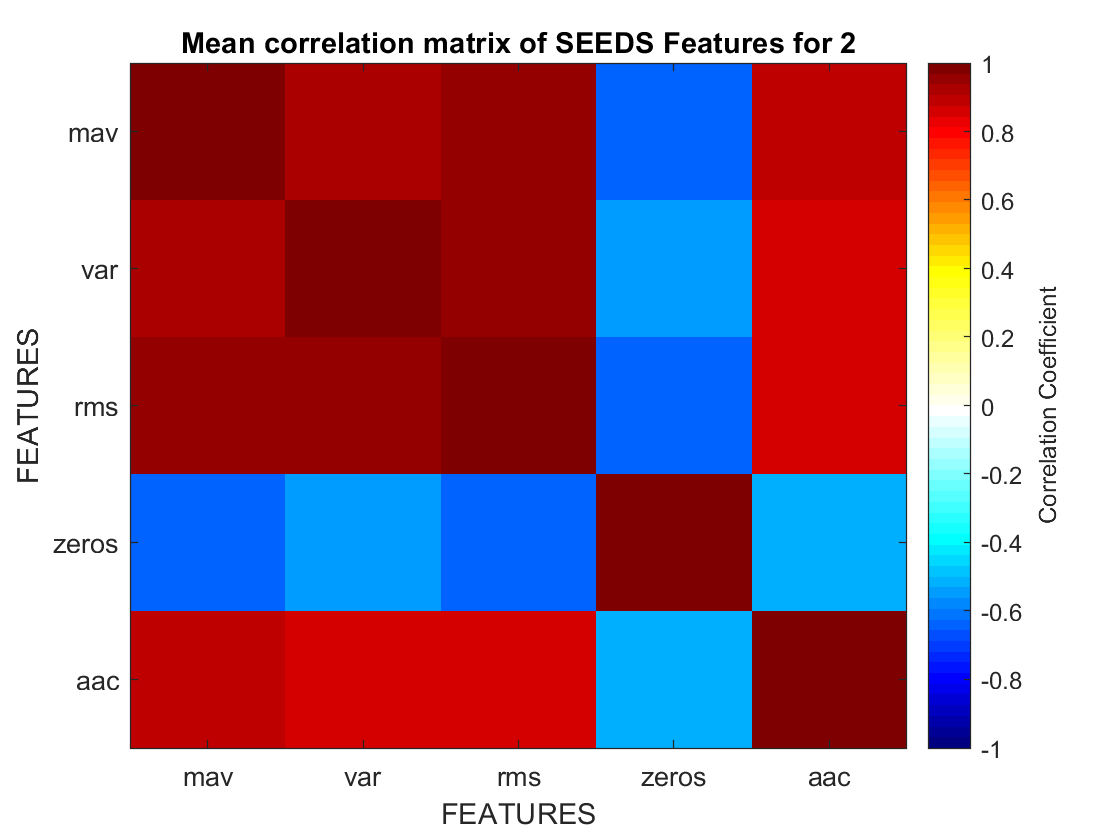

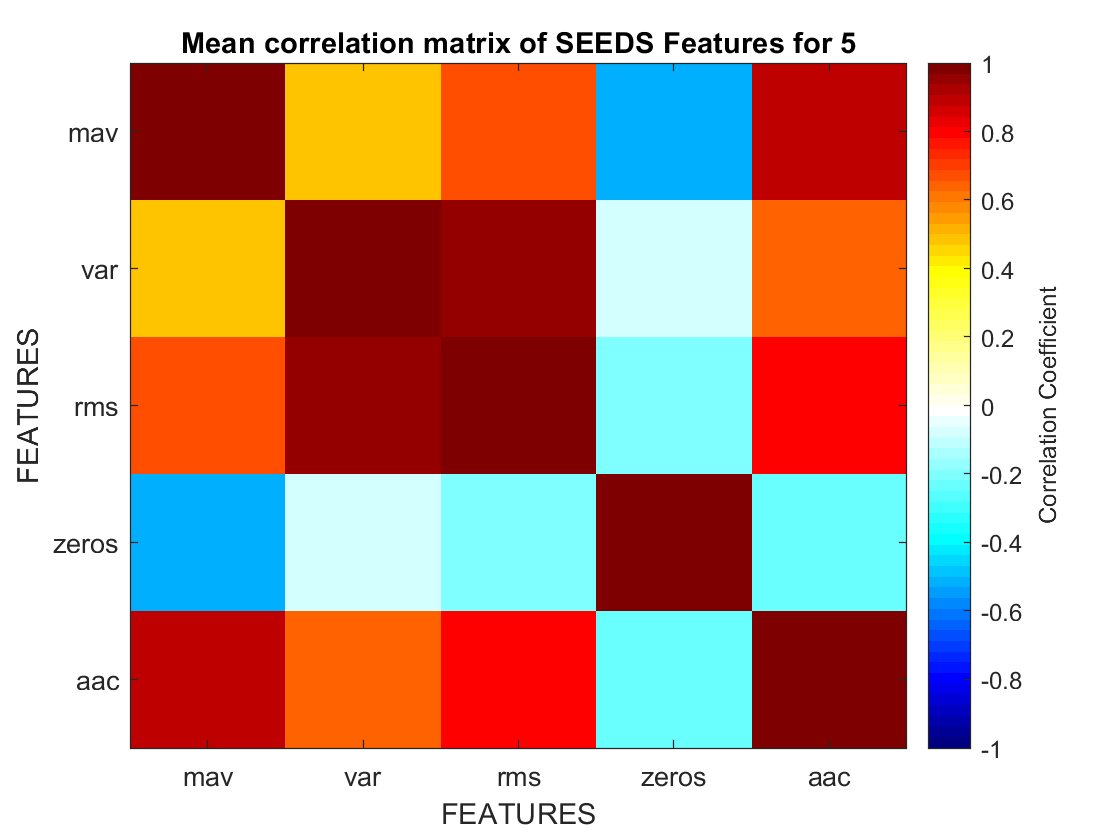

includedsubjectnumbers = [1 2 5]; %total number of subjects we will examine. This is a temporary fix. I want Matlab to calculate this.

for s = 1:length(includedsubjectnumbers) %iterate through each subject  
    load(strcat(dir_input,'subj',num2str(includedsubjectnumbers(s),'%02.f'),fname_input,'_speed',includedspeeds{sp},'.mat')) %load data for the subject
    corr_mat(:,:,s) = featureCorrelationFunc(includedchannels, includedfeatures, traindata); %For each subject, call featureCorrelationFunc.m
    figure %to ensure we don't delete our old figure each time the loop runs
    plot_feat_corr(corr_mat(:,:,s),includedfeatures,includedsubjectnumbers(s)); %input subject number if you want this in the title
end

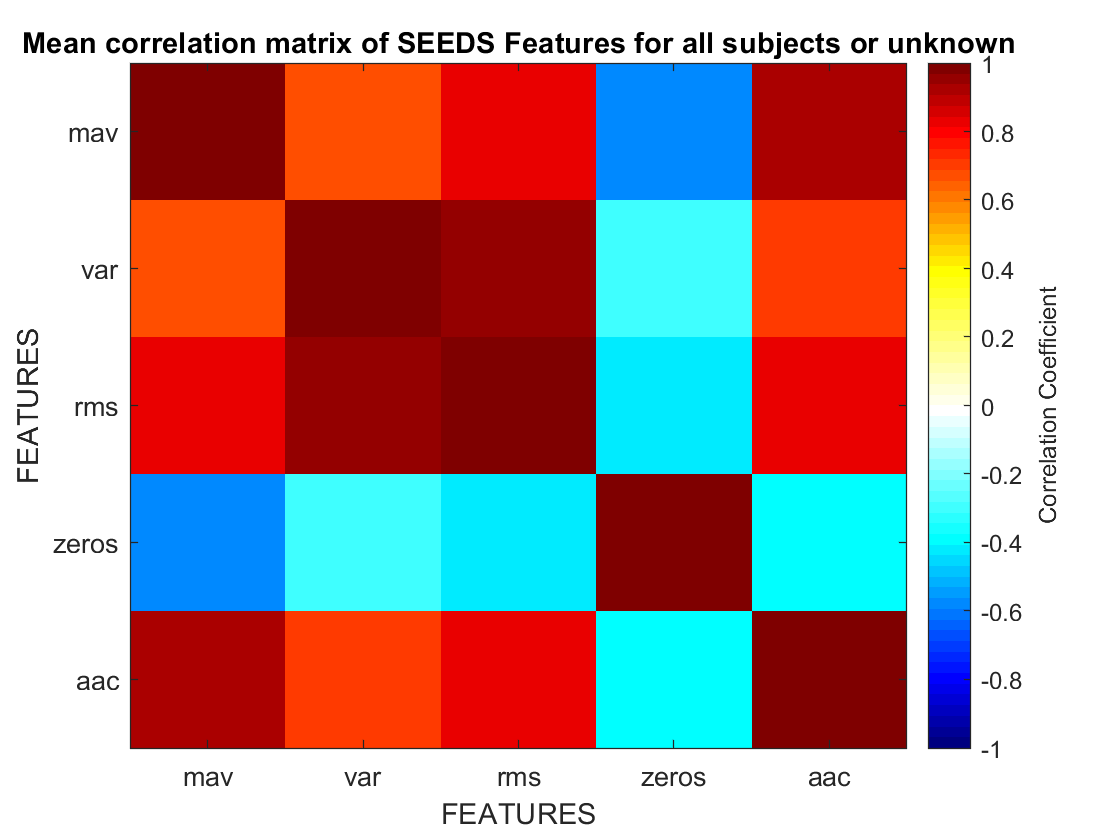

meansubjcorrmat = mean(corr_mat,3); %mean of corr coeffs for all features across channels measured (size = #features x #features x 1)
figure
plot_feat_corr(meansubjcorrmat,includedfeatures)

%meansubjcorrmat = mean(corr_mat,3) %average corr matrix across all subjects

% imagesc(meansubjcorrmat) %visual of mean subject correlation matrix 
% title('Mean correlation matrix of SEEDS Features for includedsubjects');
% xlabel('FEATURES');
% xticks([1 2 3 4 5]); %temporary fix for #features - ideally would like to have name of feature as a tick. 
% yticks([1 2 3 4 5]); %same as x tick
% ylabel('FEATURES');
% c = colorbar;
% caxis([-1 1]); %limits for colorbar
% c.Label.String = 'Correlation Coefficient';
% xticks(1:length(includedfeatures));
% xticklabels(includedfeatures);% Label x axis
% yticks(1:length(includedfeatures));
% yticklabels(includedfeatures);% Label y axis
    

%fds = fileDatastore('*_speedboth.mat', 'ReadFcn', @importdata) %finds all mat files in google drive
%fullFileNames = fds.Files % array of all mat files
%numFiles = length(fullFileNames) %counts num of mat files

Matlab wasn't recognizing the function call in the previous section, so I have pasted the function below as a temporary fix.

function [] = plot_feat_corr(corrmat,includedfeatures, varargin)
if length(varargin) == 1
    subj = num2str(varargin{1});
else
    subj = 'all subjects or unknown';
end
cmapwj = load('./colormapjetwhite.mat');
colormap(cmapwj); % set colormap
imagesc(corrmat) %visual of mean correlation matrix 
title(['Mean correlation matrix of SEEDS Features for ' subj] );
xlabel('FEATURES');
set(gca, 'XTick', 1:size(corrmat)); % center x-axis ticks
set(gca, 'YTick', 1:size(corrmat)); % center y-axis ticks
ylabel('FEATURES');
c = colorbar;
caxis([-1 1]); %limits for colorbar
c.Label.String = 'Correlation Coefficient';
xticks(1:length(includedfeatures));
xticklabels(includedfeatures);% Label x axis
yticks(1:length(includedfeatures));
yticklabels(includedfeatures);% Label y axis
end
